# 单层感知器

%单层感知器相关函数
%实例4.1
p=[-1,1;-1,1];%输入向量有两个分量，两个分量取值范围均为-1~1
t=1;%共有一个输出节点
net=newp(p,t);%创建感知器
P=[0,0,1,1;0,1,0,1];%用于训练的输入数据，每列是一个输入向量
T=[0,1,1,1];%输入数据的期望输出
net=train(net,P,T);
newP=[0.9,0.9]';
newT=sim(net,newP)

newT = 1

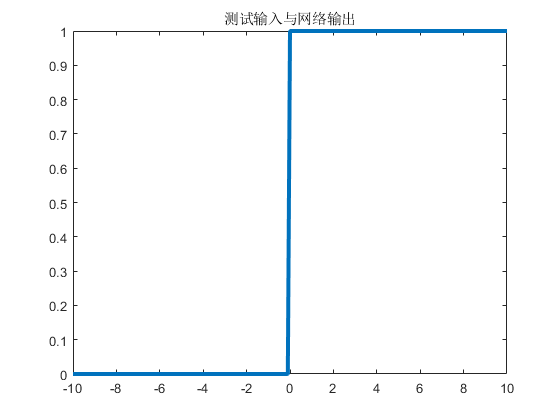

%创建感知器，用来判断输入数字的符号，非负数输出1，负数输出0
%实例4.2
p=[-100,100];%一行一个输入，对应的两列的值是下限和上限
t=1;%输出节点有一个
net=newp(p,t);
P=[-5,-4,-3,-2,-1,0,1,2,3,4];%训练输入
T=[0 0 0 0 0 1 1 1 1 1];%训练输出（期望达到的值）
net=train(net,P,T);%训练网络
newP=-10:0.1:10;
newT=sim(net,newP);
title('测试输入与网络输出');

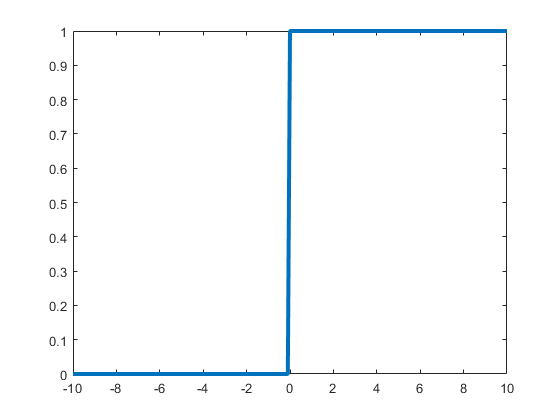

plot(newP,newT,'linewidth',3);

%使用感知器解决简单分类问题
x = [-5,-4,-3,-2,-1,0,1,2,3,4,5];%训练输入
t = [0 0 0 0 0 1 1 1 1 1 1];%期望输出
net = perceptron;
net = train(net,x,t);
view(net)
y = net(x);
newP=-10:0.1:10;
newT=sim(net,newP);
title('测试输入与网络输出');

plot(newP,newT,'linewidth',3);

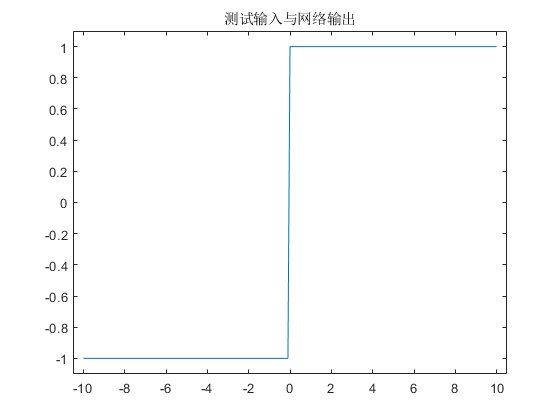

%使用感知器解决简单分类问题,仿真时直接使用网络，传入输入值即可
x = [-5,-4,-3,-2,-1,0,1,2,3,4,5];%训练输入
t = [0 0 0 0 0 1 1 1 1 1 1];%期望输出
net = perceptron;
net = train(net,x,t);
view(net)
y = net(x);
newP=-10:0.1:10;
title('测试输入与网络输出');

plot(newP,net(newP),'linewidth',3);

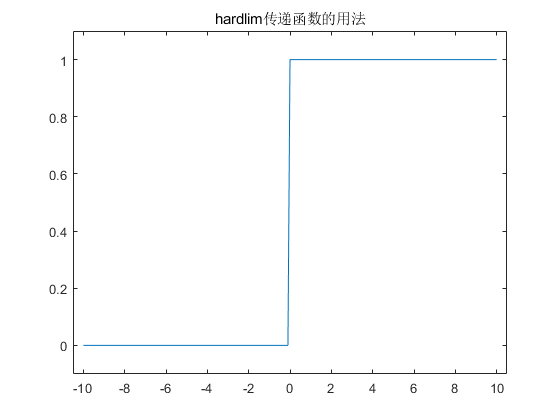

%下面展示hardlim传递函数的用法
n=-10:0.1:10;
plot(n,hardlim(n));
title('hardlim传递函数的用法')
axis([-10.5,10.5,-0.1,1.1]);

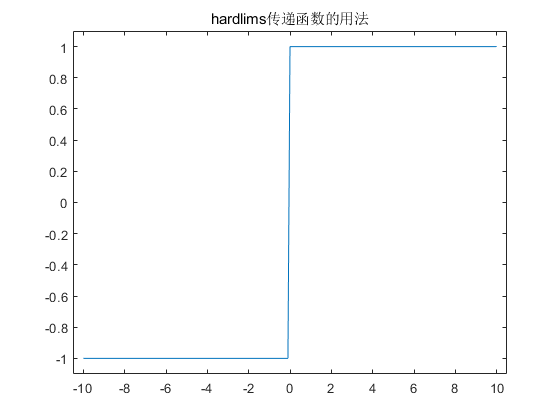

%下面展示hardlims传递函数的用法
n=-10:0.1:10;
plot(n,hardlims(n));
title('hardlims传递函数的用法')
axis([-10.5,10.5,-1.1,1.1]);

# **BP神经网络**

**logsig传递函数**

**logsig(n)=**$\frac{1}{1+e^{-n} }$

该函数使得接近原点的数据被放大，偏离原点的数据则被放大

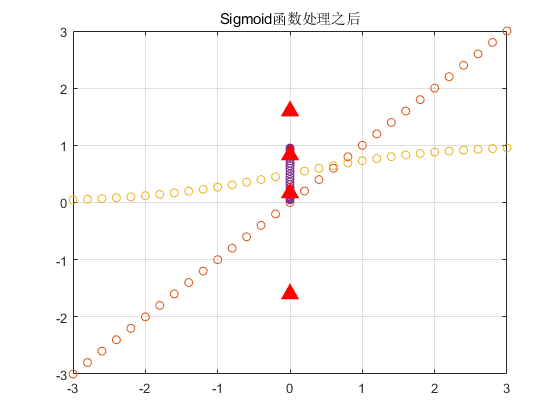

clear
x=-3:0.2:3;
plot(x,x,'o')
hold on;
plot([0,0],x([8,24]),'^r','Linewidth',4);%将原始数据投射到Y轴
y=logsig(x);
figure(2);
plot(x,y,'o');
hold on;
plot(zeros(1,length(y)),y,'o')
plot([0,0],y([8,24]),'^r','LineWidth',4)
grid on
title('Sigmoid函数处理之后')

transig(Tan-sigmoid函数)

tansig(n)=$\frac{e}{1+e^{-2n} }-1$

绘制该函数曲线

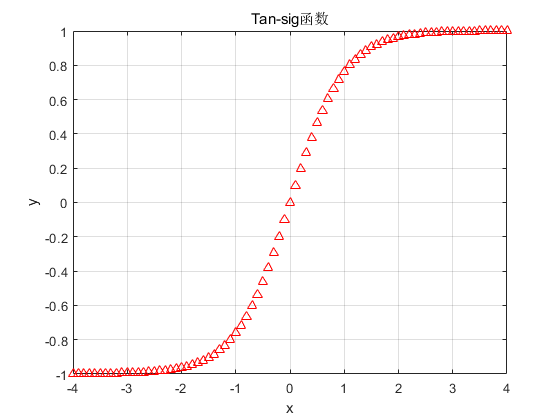

x=-4:0.1:4;
y=tansig(x);
plot(x,y,'^r')
title(['Tan-sig函数' ])
xlabel('x');
ylabel('y');
grid on

例子蝗虫问题

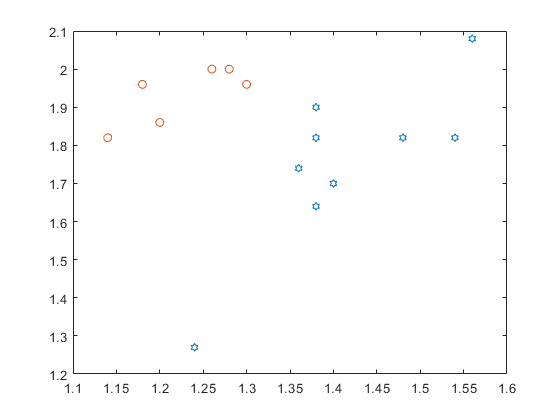

clear
p1=[1.24,1.27;1.36,1.74;1.38,1.64;1.38,1.82;1.38,1.90;
1.40,1.70;1.48,1.82;1.54,1.82;1.56,2.08];
p2=[1.14,1.82;1.18,1.96;1.20,1.86;1.26,2.00
1.28,2.00;1.30,1.96];
p=[p1;p2]';
pr=minmax(p);
goal=[ones(1,9),zeros(1,6);zeros(1,9),ones(1,6)];
plot(p1(:,1),p1(:,2),'h',p2(:,1),p2(:,2),'o')

net=newff(pr,[3,2],{'logsig','logsig'});

          See help for NEWFF to update calls to the new argument list.
 


net.trainParam.show = 10;
net.trainParam.lr = 0.05;
net.trainParam.goal = 1e-10;
net.trainParam.epochs = 50000;
net = train(net,p,goal);
x=[1.24 1.80;1.28 1.84;1.40 2.04]';
y0=sim(net,p)

y0 =     1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000    1.0000    1.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0003
    0.0000    0.0001    0.0001    0.0001    0.0006    0.0001    0.0002    0.0003    0.0003    0.9996    0.9998    0.9998    0.9999    0.9999    0.9997


y=sim(net,x)

y =     0.0002    0.0016    0.9988
    0.9998    0.9986    0.0079
